# Implementación digital de controladores

En este script vamos a realizar la implementación de un controlador digital de un controlador digital para el ángulo del motor DC del laboratorio. En un experimento de identificación obtuvimos el siguiente modelo:


$$$G(s)=\frac{\theta(s)}{U(s)}= \frac{1232.9}{s(0.33\,s+1)}$$


Asimismo, para este sistema hemos obtenido el siguiente controlador, usando un método de diseño frecuencial:


$$$C(s)= \frac{0.05506 (s+26) (s+3.055)}{s^2 + 40.72s + 613.4$.$$


s = tf("s");
G = 1232.9/(s*(0.33*s+1));
Controller  = 0.05506*(s + 26)*(s + 3.055)/(s^2 + 40.72*s + 613.4);
%Controller = 0.039597*(s+43.11)*(s+4.222)*(s+3.333)*(s^2 + 21.02*s + 256)/(s* (s+19.05)* (s+11.2) *(s^2 + 22.81*s + 544.2))

## Paso 1: selección del tiempo de muestreo

Para encontrar el tiempo de muestreo apropiado, calculamos la respuesta en frecuencia del sistema de lazo cerrado.

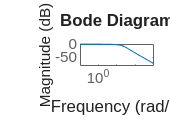

T = feedback(Controller*G, 1);
bodemag(T)

Y encontramos la frecuencia de corte del sistema realimentado en Hz

fb = bandwidth(T)/(2*pi)

fb = 2.0115

La recomendacíón nos dice que la frecuencia de muestreo debe *al menos *mayor que $$10\times f_b$$

fh = 10*fb

fh = 20.1155

Y por consiguiente,

hmax = 1/fh;
fprintf('El tiempo de muestreo tiene que ser menor a %0.2f segundos', hmax);

El tiempo de muestreo tiene que ser menor a 0.05 segundos

**Nota: para el motor DC un tiempo de muestreo de 0.01s  (**$$f_h \approx 50 f_b$$**) es una buena elección.**

## Paso 2: discretización del controlador

Para discretizar el controlador se usa la transformación bilineal definida como:


$$$C_d(z) = \left. C(s) \right|_{s= \frac{2}{h}\frac{z-1}{z+1}}$$$


 Esto lo hacemos con los siguientes comandos:

h = 0.01;
Cdz = c2d(Controller, h, 'tustin')


Cdz =
 
  0.05182 z^2 - 0.09016 z + 0.0387
  --------------------------------
       z^2 - 1.616 z + 0.6659
 
Sample time: 0.01 seconds
Discrete-time transfer function.
Model Properties


## Paso 3: conversión a variables de estado

En este paso encontramos una realización en variables de estado para el controlador discreto de la forma:


$$$
x[n+1] = A\, x[n] + B\,e[n]
$	$$



$$$u[n] =C\,x[n] + D\,e[n] $. $$


Esto lo hacemos con el siguiente comando que permite obtener una representación modal, la cual tiene buenas características numéricas.

Cdz_estado = modalreal(Cdz) 


Cdz_estado =
 
  A = 
              x1         x2
   x1     0.8078  -0.008073
   x2      1.658     0.8078
 
  B = 
            u1
   x1  0.09692
   x2  0.07893
 
  C = 
             x1        x2
   y1  -0.06108  -0.00654
 
  D = 
            u1
   y1  0.05182
 
Sample time: 0.01 seconds
Discrete-time state-space model.


%si no funciona use simplemente para la conversion de estado use ss(Cdz)

## Paso 4: Control Anti-windup

Calculamos la ganancia $L$ del control de antiwindup con el método de Kalman, mediante el comando siguiente

[kalmf,L,P] = kalman(Cdz_estado, 1e6, 1, 0);

## Paso 5: Implementación del código del controlador

Obtenemos las matrices $A,B,C$ y $D$ del controlador discretizado, representado en variables de estado:

[A, B, C, D] = ssdata(Cdz_estado);

Obtenemos las matrices $A_{aw}$ y $B_{aw}$

Baw = B - L*D;
Aaw = A - L*C;

Por último, utilizamos la siguiente función creada para esta guia, que escribe automaticamente el código del controlador en el archivo `controller.h`

generatecode(Aaw,Baw, C, D, L)

code for controller has been generated
